%% Problem 6.2 w-Plane %%

Run each section at a time if graphs are not showing.

ASSUME:

 d2c w/ 'tustin' selection is equivalent to converting from z- to w-plane. 

PROCEDURE:

The basic procedure is to convert Gs to Gz using zoh with c2d function, then convert Gz to Gw using the d2c function with 'tustin' option. Then use this Gw to design series compensator Hw. Then convert Hw to Hz using c2d function with 'tustin' option (or my own version myDiscretize).

s = tf('s');
syms Ra La Kt Kv Bm;
Ra = 1;
La = .001;
Kt = 5;
Kv = 5;
Bm = 20;
J = 1;
A = [-Ra/La -Kv/La 0; Kt/J -Bm/J 0; 0 1 0];
B = [1/La; 0; 0];
C = [0 0 1];
[num, den] = ss2tf(A, B, C, 0);
A_ip = [0 0 1 0; 0 0 0 1; 0 11.5 -1.84e-3 -8.08e-5; 0 7.2 -8.16e-4 -9.18e-5];
B_ip = [0 0 .0184 .00816]';
C_ip = [1 0 0 0; 0 1 0 0];
C_ip_p = C_ip(1,:);
C_ip_theta = C_ip(2,:);
D_ip = [0];
sys_ip_p = ss(A_ip, B_ip, C_ip_p, D_ip);
sys_ip_theta = ss(A_ip,B_ip, C_ip_theta, D_ip);

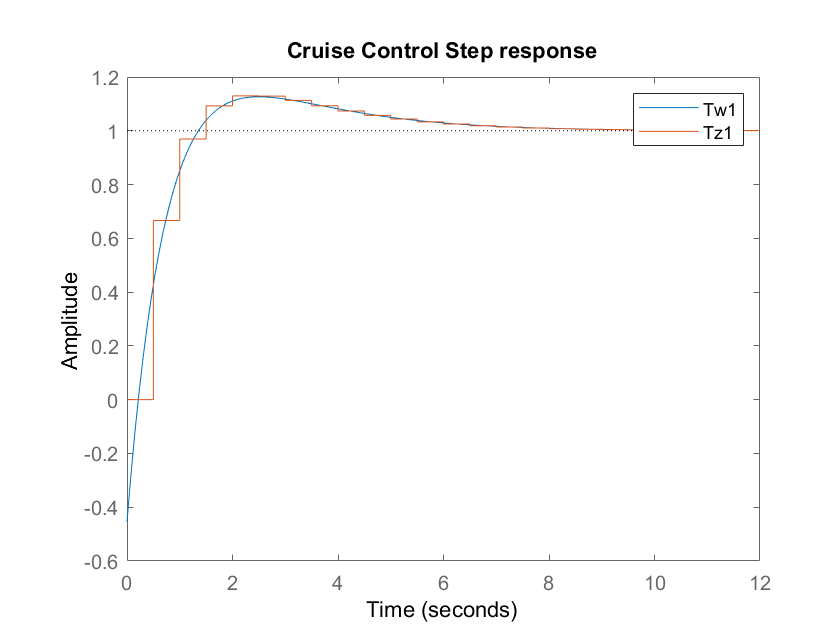

%% 5.1 %%
close all;
Gs1 = 1/(8*s+1);
h1 = 0.5;
z1 = tf('z', h1);
Gz1 = c2d(Gs1, h1);
Gw1 = d2c(Gz1, 'tustin'); % Equivalent of w transform
P1 = 10;            
I1 = 4;
Hw1 = tf(P1 + I1/s);
Tw1 = feedback(Hw1*Gw1, 1);
figure;
step(Tw1);
hold on;
Hz1 = myDiscretize(Hw1, h1, 'tustin');
Tz1 = feedback(Hz1*Gz1, 1);
step(Tz1);
title('Cruise Control Step response')
legend;
hold off;

%% 5.2 %%
close all;
Gs2 = tf(num, den);
h2 = .005;
z2 = tf('z', h2);
Gz2 = c2d(Gs2, h2);
Gw2 = d2c(Gz2, 'tustin');
lead_phase = 30;
K_2 = 50;                               % SOME TRIAL AND ERROR
Beta_2 = 3;
w1_2 = .111/sqrt(Beta_2);
Hw2 = (1+s/w1_2)/(1+s/(Beta_2*w1_2));
figure;
margin(K_2*Hw2*Gw2);
title("DC motor compensated stability margins");
figure;
step(feedback(Hw2*K_2*Gw2, 1));
title("DC motor compensated step response");

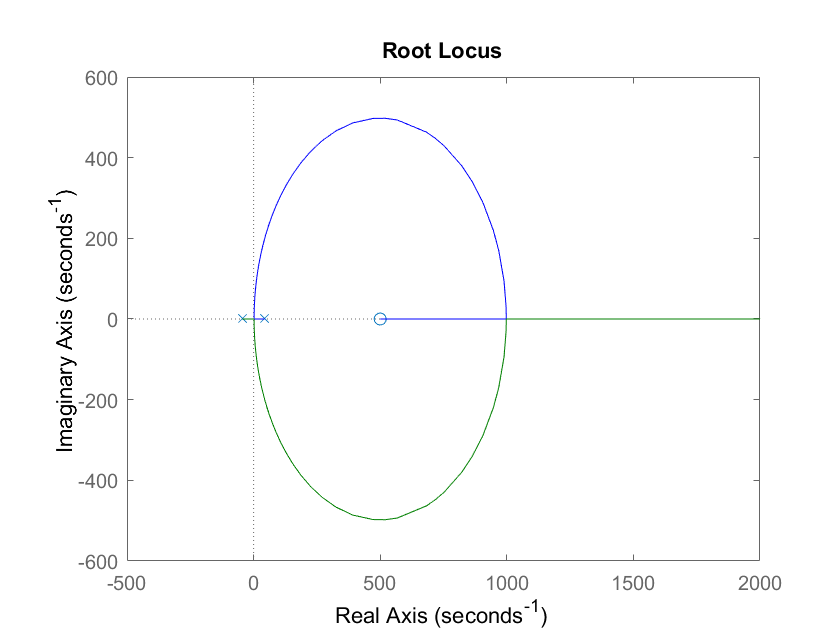

%% 5.3 Maglev %%
close all;
Gs3_mag = -28.1/(s^2 - 1962); 
Gs3_mag_neg = -1 * Gs3_mag;
h3_mag = .004;
Gz3_mag_neg = c2d(Gs3_mag_neg, h3_mag);
Gz3_mag = -1*Gz3_mag_neg;
z3_mag = tf('z', h3_mag);
Gw3_mag_neg = d2c(Gz3_mag_neg, 'tustin');
figure;
rlocus(Gw3_mag_neg);

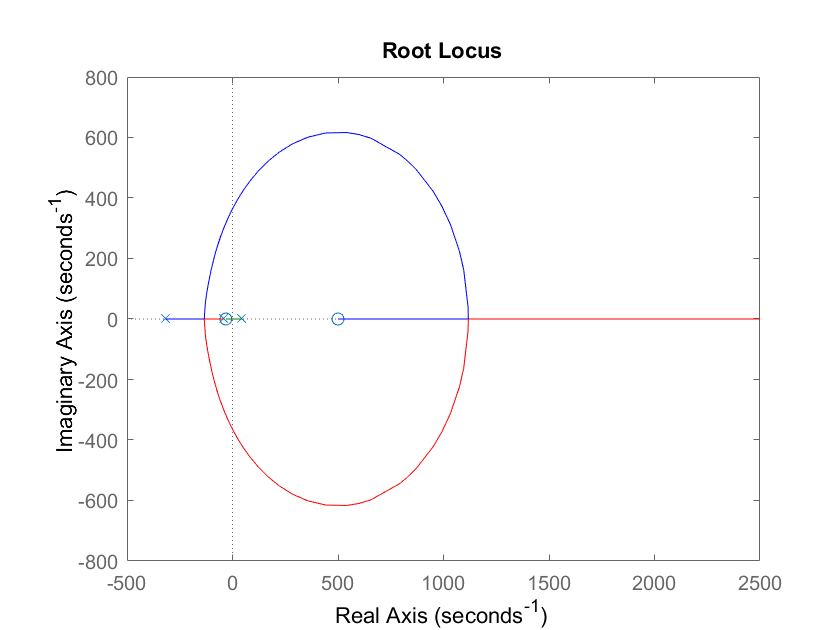

w_c_3 = 100;                               
phi_max_3a = 55;
beta_3a = (1+sind(phi_max_3a))/(1-sind(phi_max_3a));
w_3a = w_c_3/sqrt(beta_3a);                
Hw3_mag = (1+s/w_3a)/(1+s/(w_3a*beta_3a));
figure;
rlocus(Hw3_mag*-1*Gw3_mag);

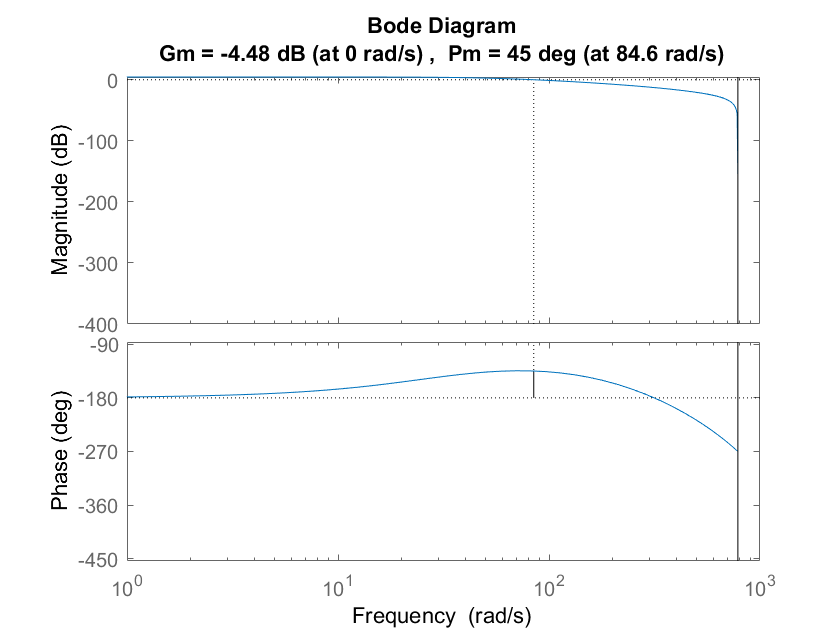

K3_mag = -117;
Hz3_mag = c2d(K3_mag*Hw3_mag, h3_mag, 'tustin');
LG3_mag = Gz3_mag*Hz3_mag;
figure;
margin(LG3_mag);

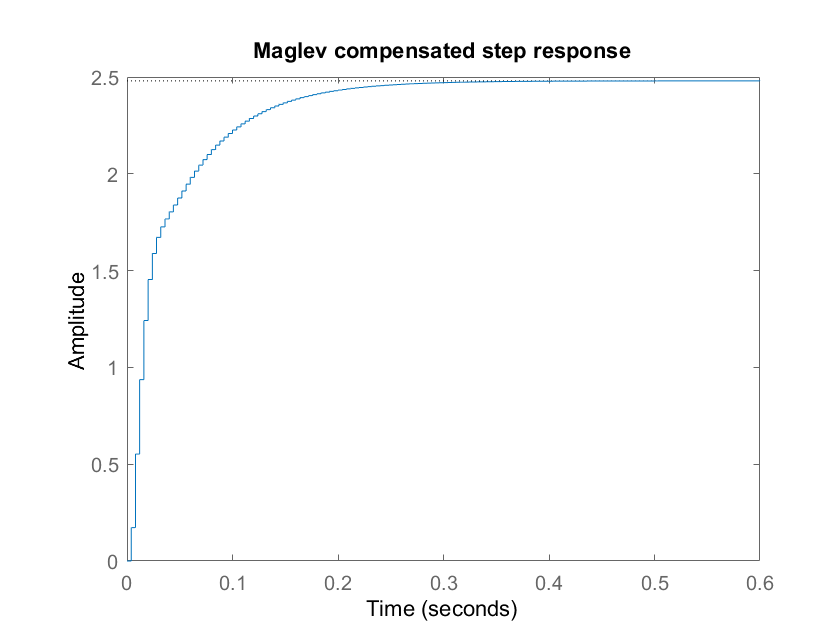

figure;
step(feedback(LG3_mag, 1));
title('Maglev compensated step response');

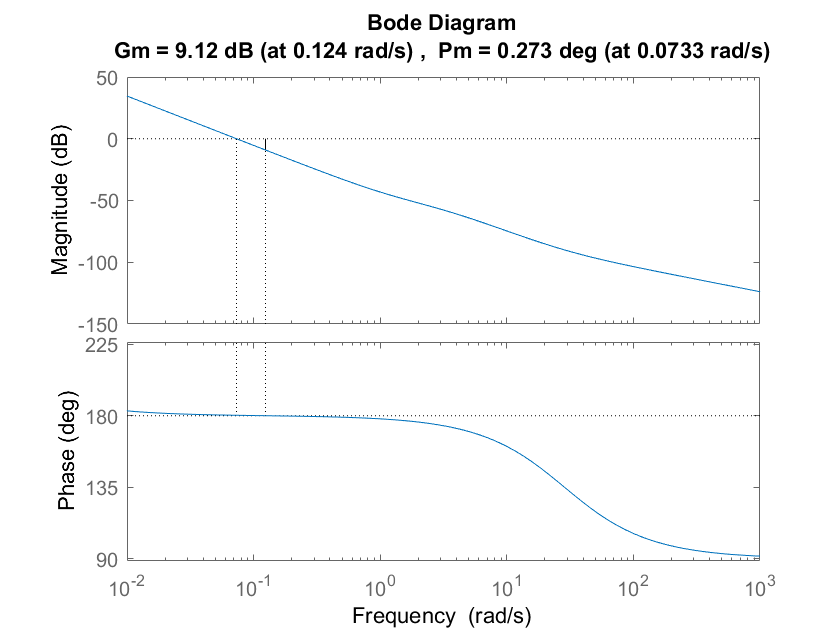

%% 5.3 Inverted Pendulum position %%
close all;
Gs3_ip_p = tf(sys_ip_p);
h3_ipp = .07;
z3_ipp = tf('z', h3_ipp);
Gz3_ip_p = c2d(Gs3_ip_p, h3_ipp);
Gz3_ip_p_neg = -1*Gz3_ip_p;
Gw3_ip_p = d2c(Gz3_ip_p, 'tustin');
figure;
margin(Gw3_ip_p);

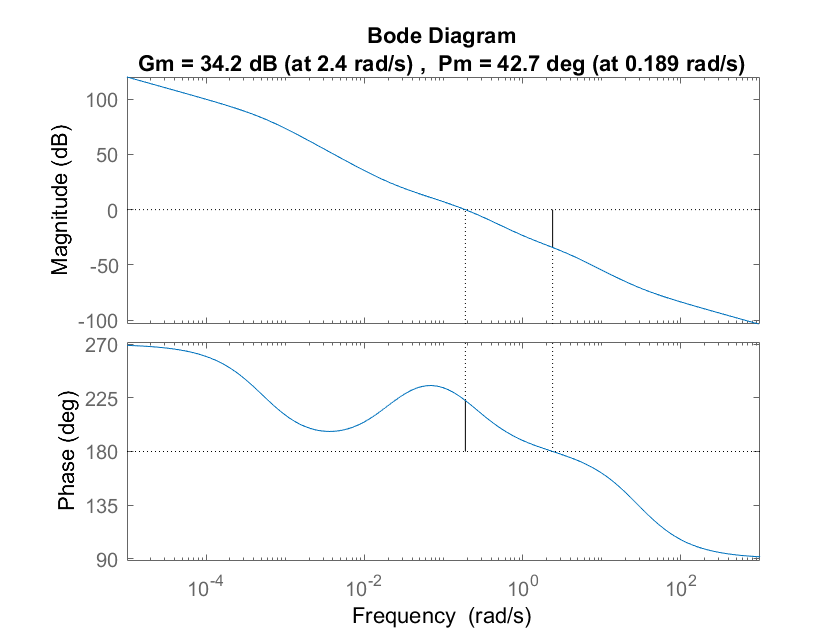

w_c_3ipp = 0.07;                              
phi_max_3a = 55;
beta_3a = (1+sind(phi_max_3a))/(1-sind(phi_max_3a));
w_3a = w_c_3ipp/sqrt(beta_3a);                
Hw3_ipp = (1+s/w_3a)/(1+s/(w_3a*beta_3a));
figure;
margin(Hw3_ipp*Gw3_ip_p);

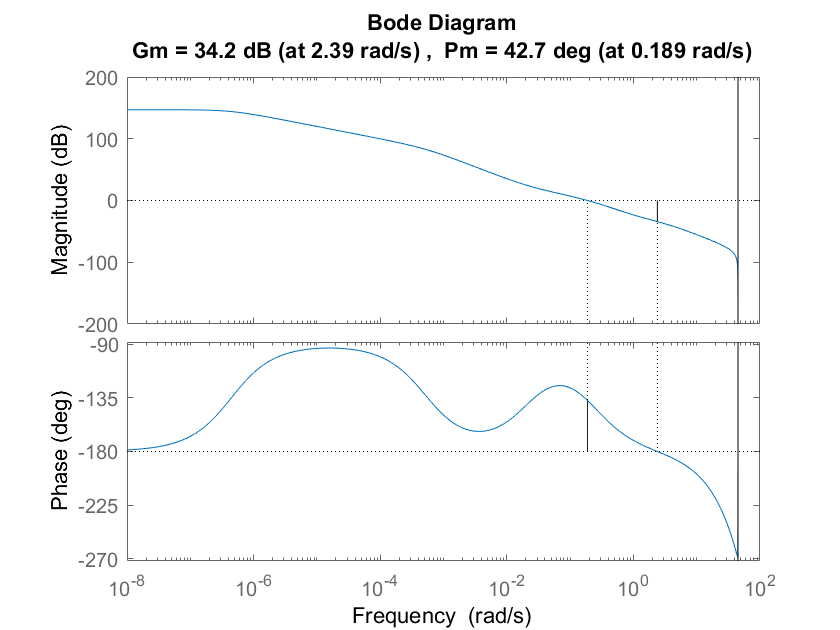

Hz3_ipp = c2d(Hw3_ipp, h3_ipp, 'tustin');
LG3 = Hz3_ipp*Gz3_ip_p;
figure;
margin(LG3);

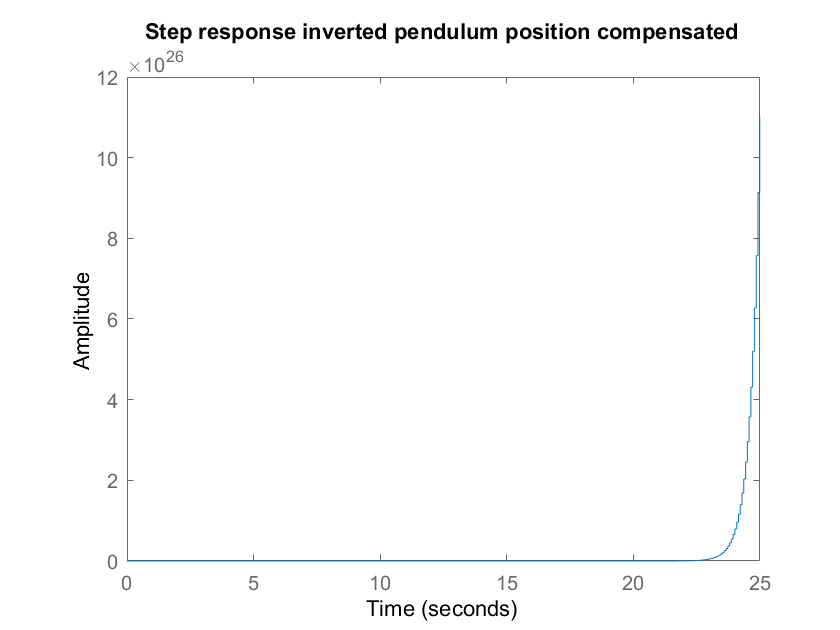

Tz3_ip_p = feedback(LG3, 1);
figure;
step(LG3);
title('Step response inverted pendulum position compensated')

% Strange! Positive margins yet the system is still unstable because of the
% RHP pole. Hard to do anything if we can't place poles where we want

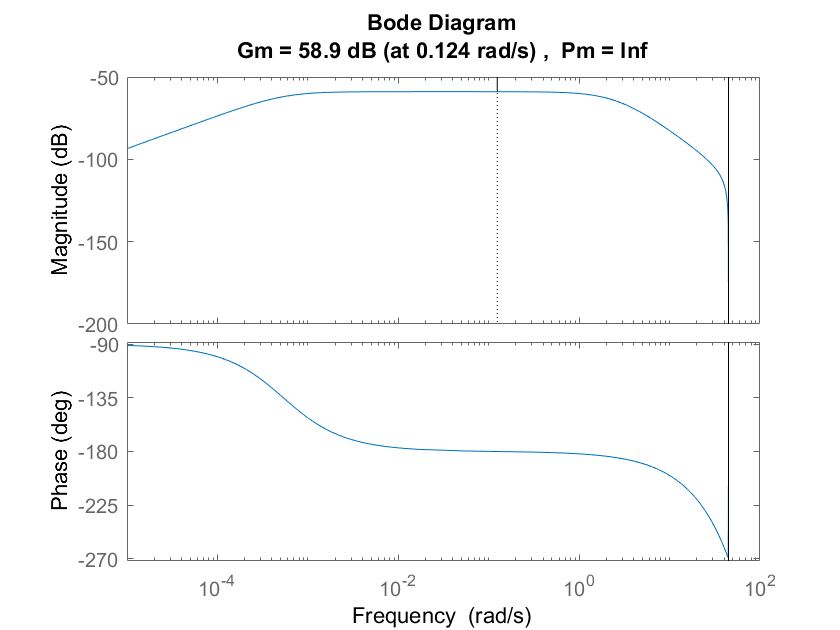

%% 5.3 Inverted Pendulum angle %%
close all;
Gs3_ip_theta = tf(sys_ip_theta);
h3_ipt = 0.07;
z = tf('z', h3_ipt);
Gz3_ip_theta = c2d(Gs3_ip_theta, h3_ipt);
figure;
margin(Gz3_ip_theta);

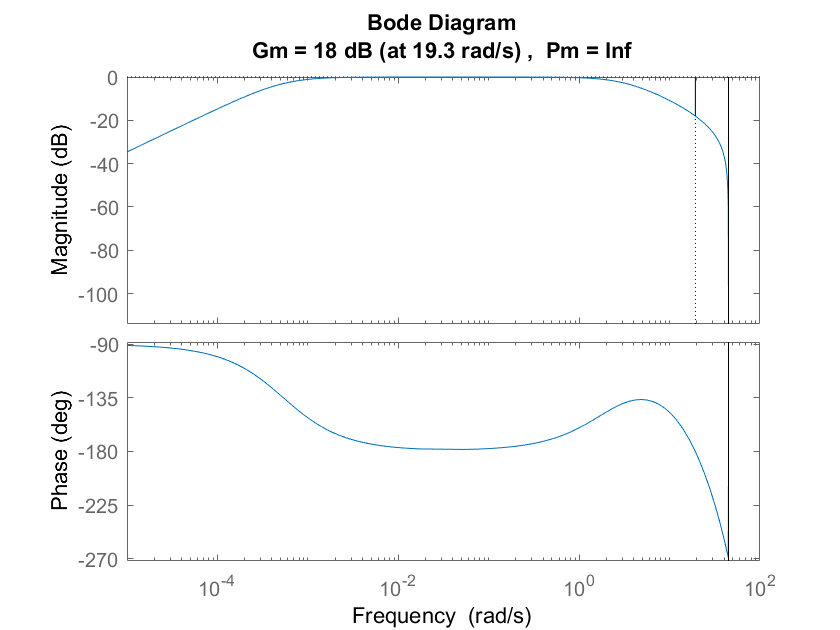

w_c_3ipp = 7;                              
phi_max_3a = 55;
beta_3a = (1+sind(phi_max_3a))/(1-sind(phi_max_3a));
w_3a = w_c_3ipp/sqrt(beta_3a);                
Hw3_ipt = (1+s/w_3a)/(1+s/(w_3a*beta_3a));
Hz3_ipt = c2d(Hw3_ipt, h3_ipt, 'tustin');
LG3 = 882*Hz3_ipt*Gz3_ip_theta;
figure;
margin(LG3);

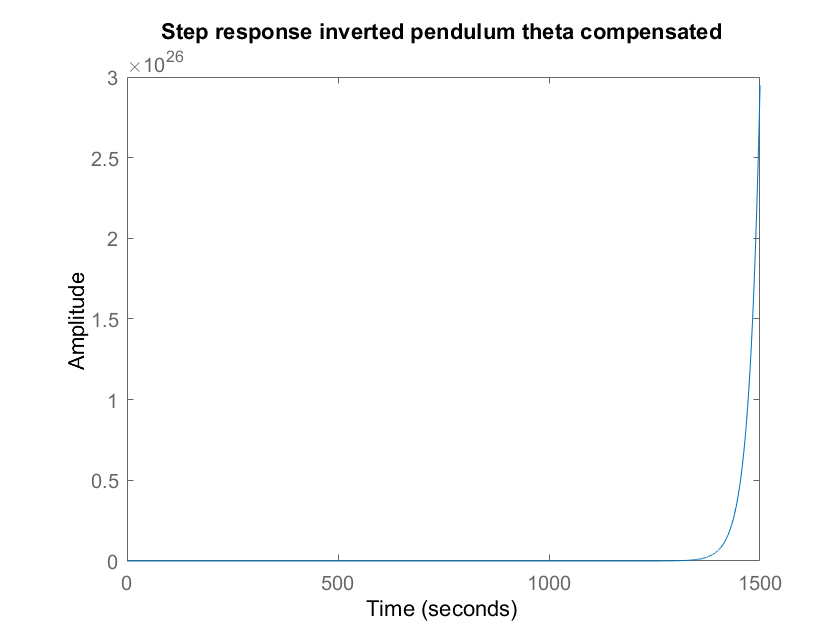

Tz3_ipt = feedback(LG3, 1);
figure;
step(Tz3_ipt);
title('Step response inverted pendulum theta compensated')

% Same problem as above

%% 5.4 %%
close all;
Gs4 = 1/(1+.08*s)^2;
h4 = 0.01;
z = tf('z', h4);
Gz4 = c2d(Gs4, h4);
Gw4 = d2c(Gz4, 'tustin');
t = 0:h4:15;
v = 6*t;
K_4 = 22;                                       %% BASED ON STEADY-STATE ERROR REQS
alpha_4 = 6.32;                                 %% BASED ON MAGNITUDE AT Wc
wc_4 = 7;                                       %% WHERE PHASE MARGIN OF 30 DEGREES WOULD BE
w1_4 = wc_4/(10*alpha_4);
Hw4 = (1/s)*(1+s/(alpha_4*w1_4))/(1+s/w1_4);
Hz4 = c2d(Hw4*K_4, h4, 'tustin');
LG4 = Hz4*Gz4;
Ts4 = feedback(K_4*Hw4*Gw4,1);
Tz = feedback(LG4, 1);
figure;
step(Ts4);
figure;
lsim(Ts4, v, t);
figure;
lsim(Tz, v, t);
figure;
margin(LG4);

%% 5.5 %%
close all;
Gs5 = tf([5],[0.05 1 0]);
h5 = 0.01;
z5 = tf('z', h5);
Gz5 = c2d(Gs5, h5);
Gw5 = d2c(Gz5, 'tustin');
K_5 = 10;
beta_5 = (1+sind(16))/(1-sind(16));
w1a_5=sqrt(1000/sqrt(beta_5)); 
Hw5 = (1+s/w1a_5)/(1+s/(w1a_5*beta_5));
figure;
step(feedback(Hw5*K_5*Gw5, 1));
Hz5 = c2d(Hw5, h5, 'tustin');
LG5 = Gz5*Hz5*K_5;
Tz5 = feedback(LG5, 1);
figure;
margin(LG5);
t = 0: h5: 15;
u = sin(2*t);
figure;
lsim(Tz5, u, t);

%% 5.6 %%
close all;
Gs6 = tf([-1.117 3.1472], [1 4.6429 5.3821]);
h6 = 0.08;
z6 = tf('z', h6);
Gz6 = c2d(Gs6, h6);
Gw6 = d2c(Gz6, 'tustin');
Hw6 = 1/s;
figure;
margin(Gw6);
figure;
margin(Gw6*Hw6);
wc6 = 4.12;                    
phi_max_6 = 40;
beta_6 = (1+sind(phi_max_6))/(1-sind(phi_max_6));
w6 = wc6/sqrt(beta_6); 
Hw6 = (1+s/w6)/(1+s/(w6*beta_6))*(1/s);
figure;
margin(Gw6*Hw6);
Tw6 = feedback(Gw6*Hw6, 1);
Hz6 = c2d(Hw6, h6, 'tustin');
Tz6 = feedback(Hz6*Gz6, 1);
figure;
margin(Hz6);
figure;
step(Tw6);
hold;

Current plot held


step(Tz6);
legend;
hold off;
% Settling time constraint met with 5% error margin

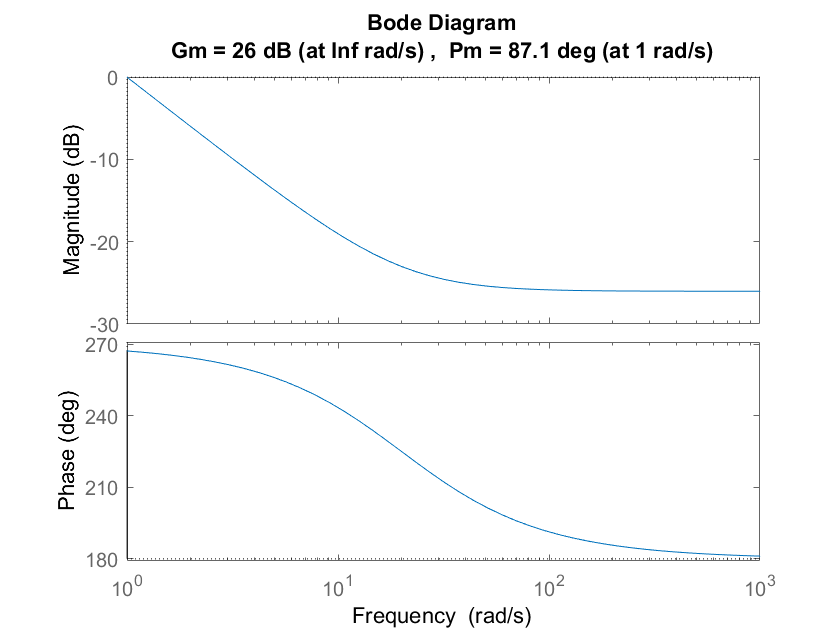

%% 5.7 %%
close all;
Gs7 = 1/s;
h7 = 0.1;
z7 = tf('z', h7);
Gz7 = c2d(Gs7, h7);
Gw7 = d2c(Gz7, 'tustin');
figure;
margin(Gw7);

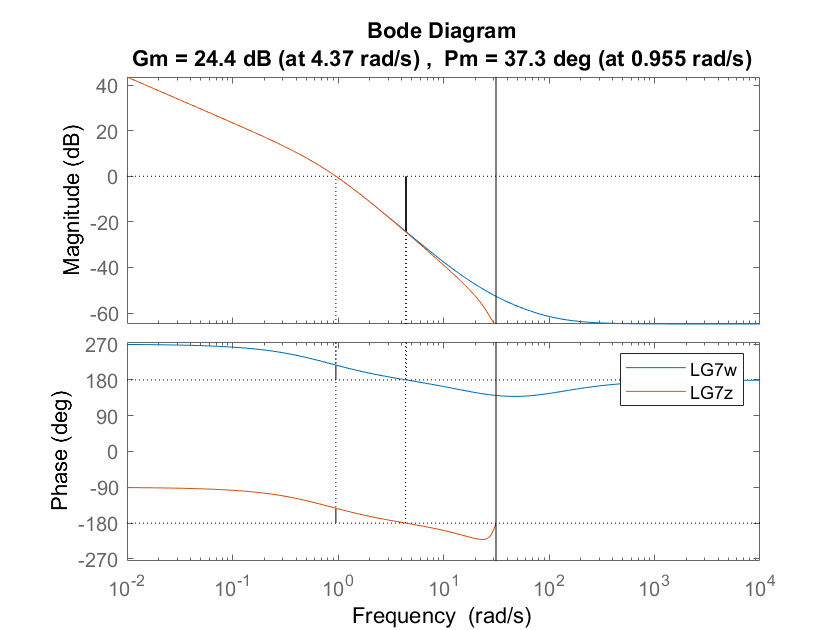

K7 = 1.5;
wc7 = 1.5;
alpha_7 = K7/wc7;                                %% BASED ON MAGNITUDE AT Wc                             
w1_7 = wc7/(10*alpha_7);
lag_7 = (1+s/(alpha_7*w1_7))/(1+s/w1_7);
wc7 = 9;
phi_max_7 = -80;
beta_7 = (1+sind(phi_max_7))/(1-sind(phi_max_7));
w7 = wc7/sqrt(beta_7); 
lead_7 = (1+s/w7)/(1+s/(w7*beta_7));
Hw7 = lag_7*lead_7*K7;
Tw7 = feedback(Hw7*Gw7, 1);
Hz7 = c2d(Hw7, h7, 'tustin');
LG7w = Hw7*Gw7;
LG7z = Hz7*Gz7;
figure;
margin(LG7w);
hold on;
margin(LG7z);
legend;
hold off;